# Design of IIR Filters (30 Points)

Dear Student, 

Welcome to Lab 4!

In the previous prelab exercise you have designed FIR filters. In this, we are going to focus on IIR filter design. Refer to the below diagram for the lab.  

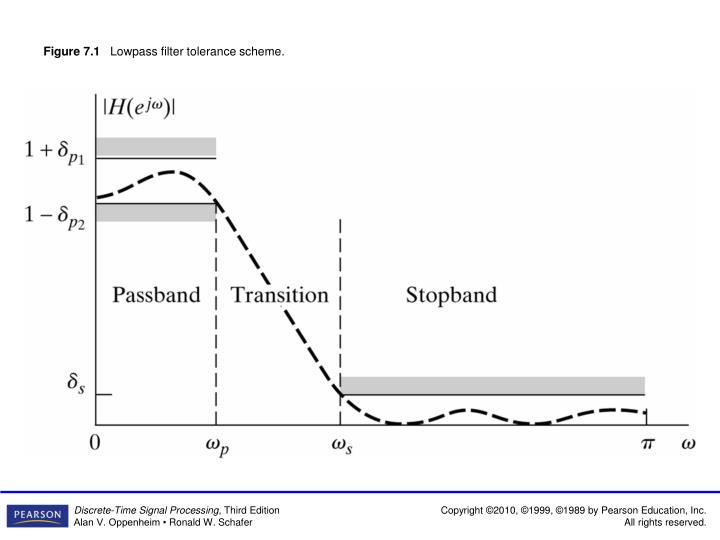

In this part, we will solve Example 5 of Chapter 7 of Oppenheim and Schafer textbook using the *filterDesigner* tool. Although you need to know how impulse invariance works, you almost never design discrete-time filters manually. Almost always, you will use some tools, such as *filterDesigner* MATLAB. 

**Note:**  From this course point of view, you should know how to manually design filters using impulse invariance for IIR filters

**References:** 

- Example 5 of Chapter 7 of Oppenheim and Shafer textbook, 3rd Edition (If you have the 2nd Edition, see Example 7.4, 7.5 and 7.6 for the IIR part starting from Page 458, and Section 7.5.1 on Page 503 for FIR part )

- [https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf](https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf)

- Relevant videos from EE321 Course.

Design the following filter: $\delta_{p_1} = \delta_{p_2} = 0.01, \;\;
\delta_s = 0.001, \;\; \omega_p = 0.4\pi, \;\; \omega_s = 0.6\pi
$using

- IIR Butterworth

- IIR Chebyshev Type 1

- IIR Chebyshev Type 2

- IIR Elliptic

and answer the following for each of the above methods: 

- Order of the filter

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

An example is shown below for IIR Butterworth filter: 

### IIR Butterworth filter

Open the Filter Designer tool, by typing *filterDesigner *in the command window as shown below. 

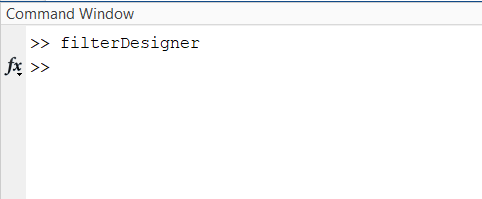

We first note that in the Filter Designer tool, for designing IIR filter,  it is assumed that $\delta_{p_1}=0
$ (red annotations in Fig. 1). Hence, in order to design the filter using this tool,  we first scale all the tolerance parameters, design the filter using the toolbox and then rescale them back.

- **Scaling the parameters:** Let $\delta_{p_1}',\; \delta_{p_2}'$and $\delta_s'$ be the new parameters.  We want to scale all the parameters according to the requirement that $\delta_{p_1}'=0$.  This implies, $1-\delta_{p_2}' = (1-\delta_{p_2})/(1+\delta_{p_1}) = (1-0.01)/1.01=  0.9802$. Hence, $\delta_{p_2}' = 1-0.9802=0.0198$. Similarly, $\delta_s' = \delta_s/(1+\delta_{p_1}) = 0.001/1.01 = 0.00099$. 

- **Filter Design:** Now, we feed these values in the Filter Designer tool  and design the filter (blue annotations in Fig. 1)

. 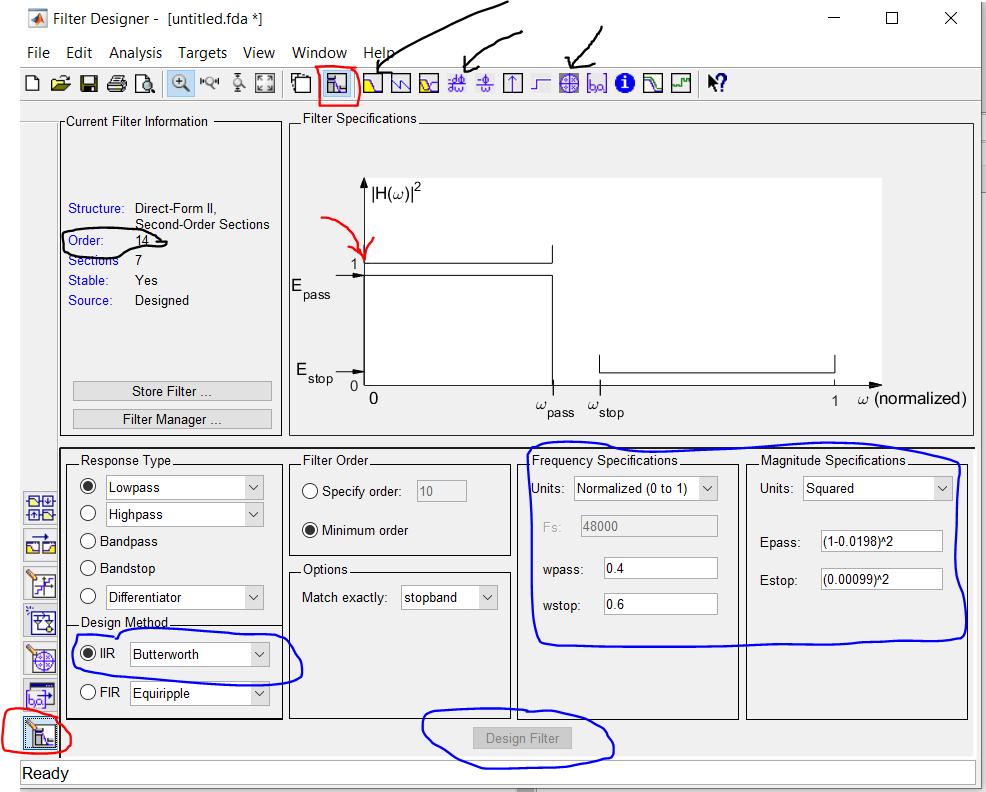

                                                      Fig 1: IIR Butterworth Filter Design

- **Rescaling parameters:**  Now, if you look at the magnitude response (by clicking on the tab besides the red annotated box), you can see that the above filter has gain of $0.9914$at $0.4\pi
$and $0.00099$at $0.6\pi$. Note that the design already satisfies the required specification. However, in some cases, if the required specification is not met, you need to rescale back the impulse response or numerator coefficients by $1+{\delta_{p_1}}$ to match the desired response. 

- **Filter Analysis: **Now, we will look at magnitude response, group delay and pole-zero plots and order of the filter (black annotations in Fig. 1). 

              - Filter order is 14. 

              - Both passband and stopbands have monotonic behaviour. 

              - There are 14 zeros at $-1$. Since all the poles are  inside the unit circle, the filter is stable. 

              - The group delay is highest in the transition band and below 15 in the passband. 

          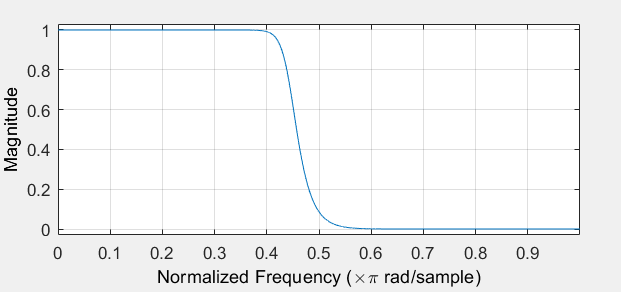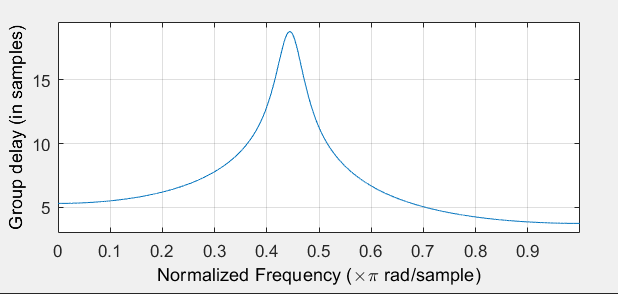

                               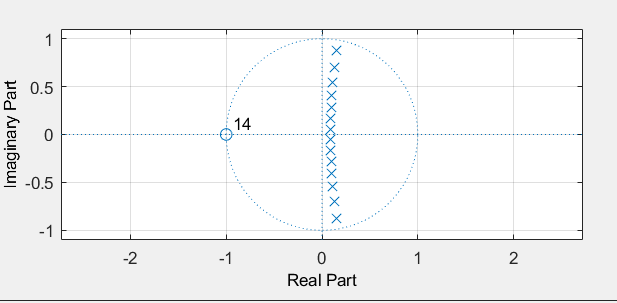

### IIR Chebyshev Type 1 (10 Points)

% Enter the filter coefficients
SOS =

    1.0000    2.0000    1.0000    1.0000   -0.4787    0.8673
    1.0000    2.0000    1.0000    1.0000   -0.6221    0.6361
    1.0000    2.0000    1.0000    1.0000   -0.8708    0.4422
    1.0000    2.0000    1.0000    1.0000   -1.0708    0.3200
    
G =

    0.3471
    0.2535
    0.1429
    0.0623
    0.9961

Answer the following:

- Order of the filter

*            ANSWER: 8*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER : P*assband has equiripple behaviour. Stopband is monotonic.

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

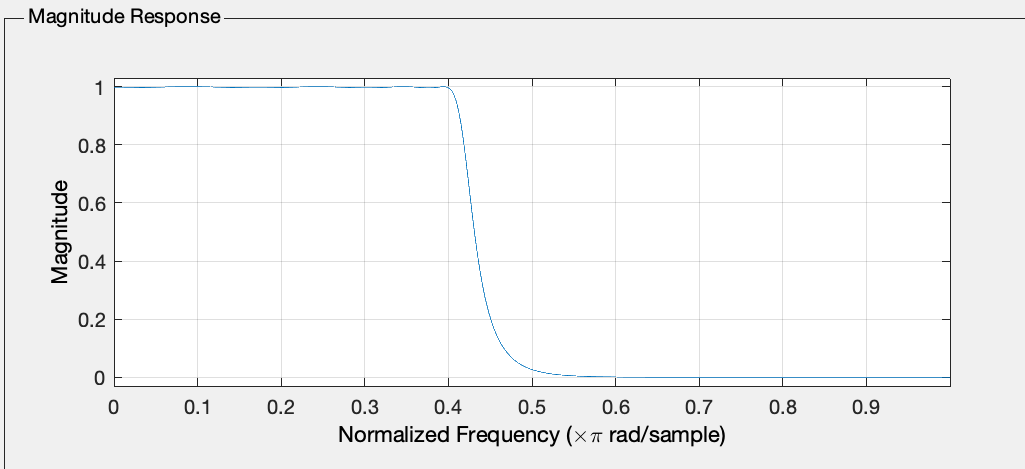

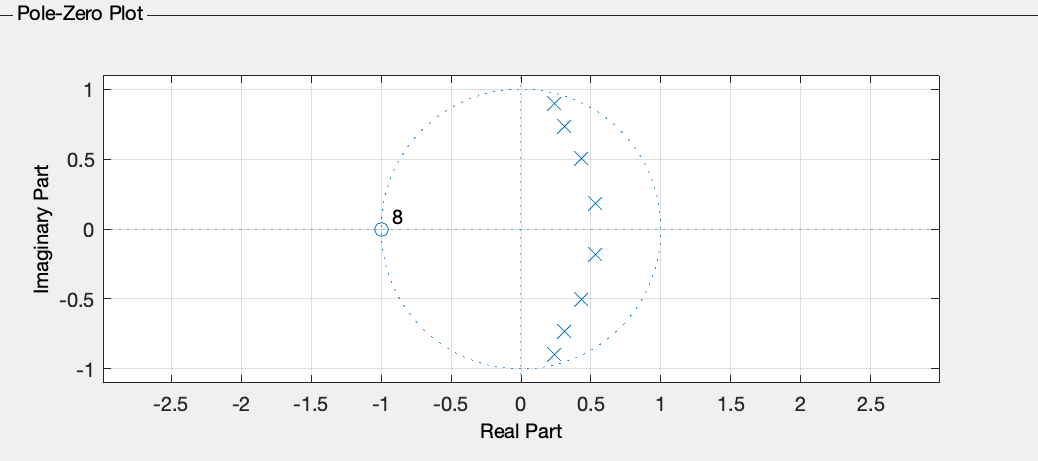

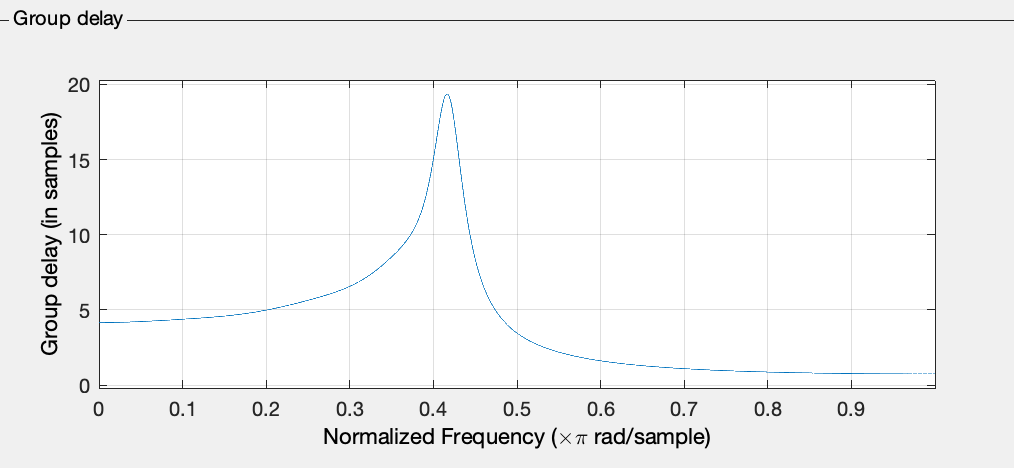

### IIR Chebyshev Type 2 (10 Points)

% Enter the filter coefficients
SOS =

    1.0000    0.6529    1.0000    1.0000   -0.1205    0.7462
    1.0000    0.9305    1.0000    1.0000   -0.0037    0.3856
    1.0000    1.4396    1.0000    1.0000    0.1254    0.1508
    1.0000    1.9212    1.0000    1.0000    0.2101    0.0281

G =

    0.6128
    0.4715
    0.3710
    0.3158
    1.0000

Answer the following:

- Order of the filter

*            ANSWER    8*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER    Stopband* has equiripple behaviour. Passband is monotonic.

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

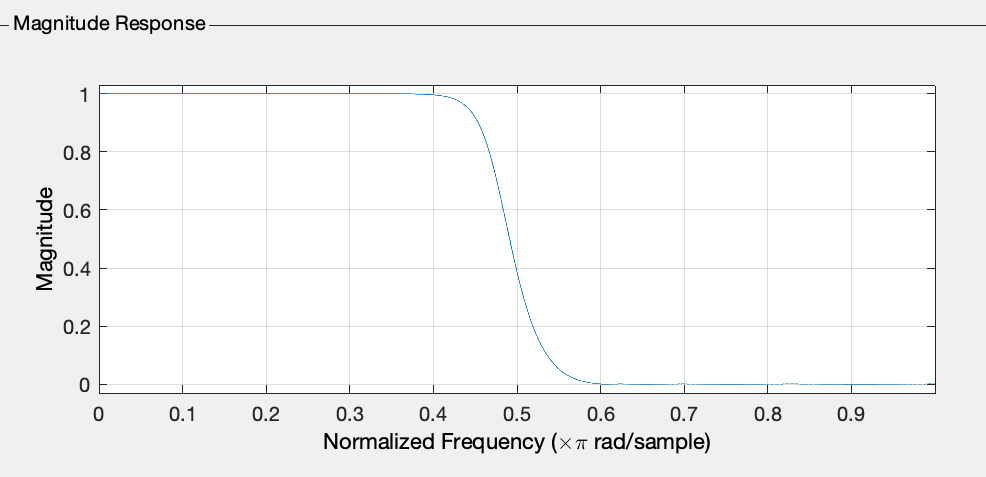

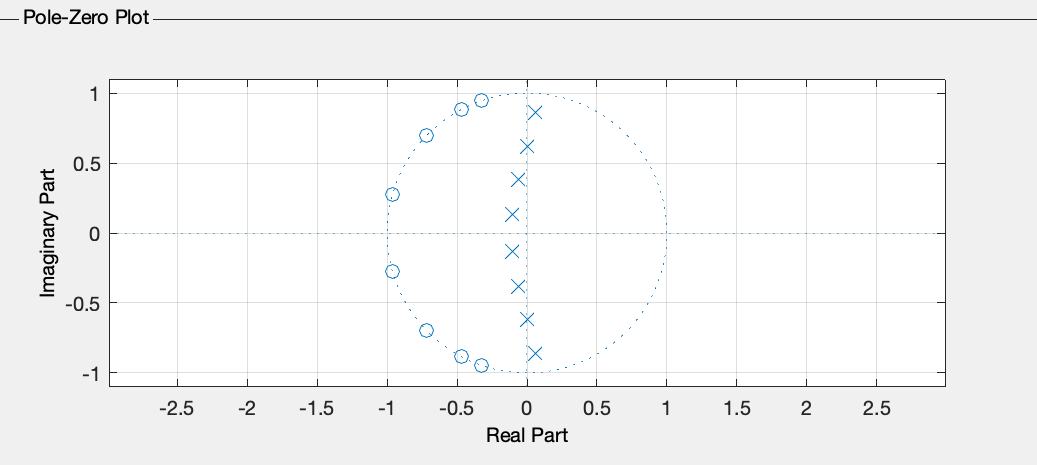

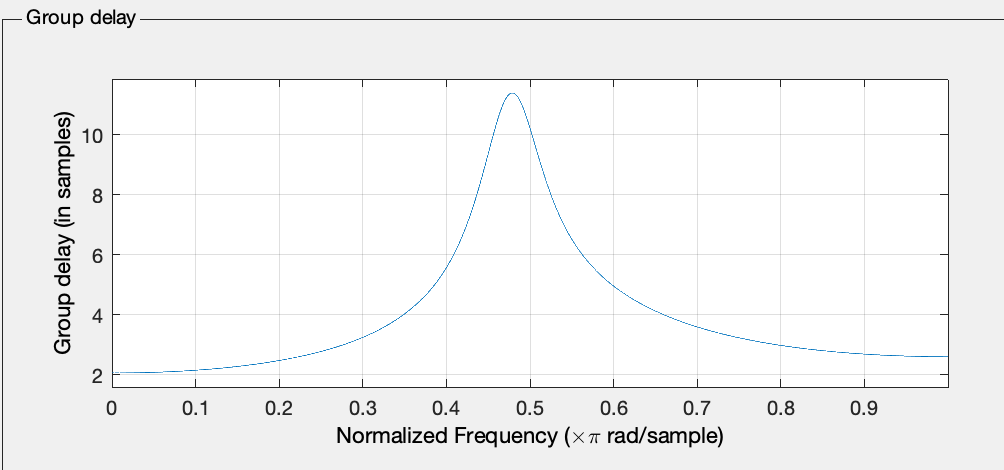

### IIR Elliptic (10 Points)

% Enter the filter coefficients
SOS =

    1.0000    1.1118    1.0000    1.0000   -0.3641    0.3992
    1.0000    1.8423    1.0000    1.0000   -0.4775    0.1072
    1.0000    0.6709    1.0000    1.0000   -0.2801    0.7836
    
G =

    0.7193
    1.6841
    0.0253
    1.0000

Answer the following:

- Order of the filter

*            ANSWER    6*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER    *Both passband and stopbands have equiripple behaviour.

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

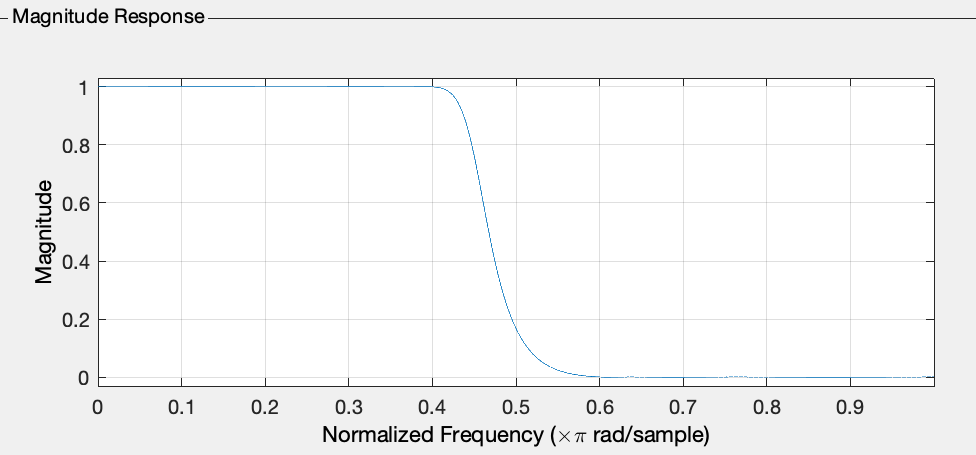

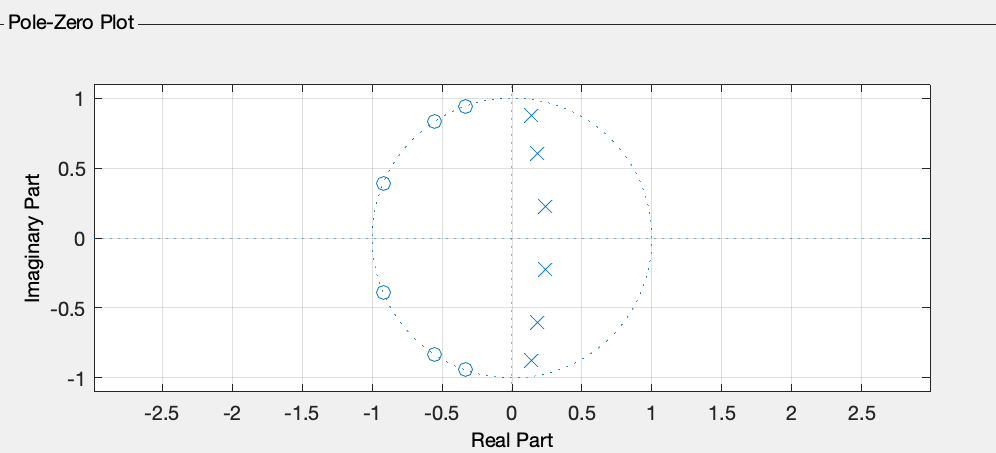

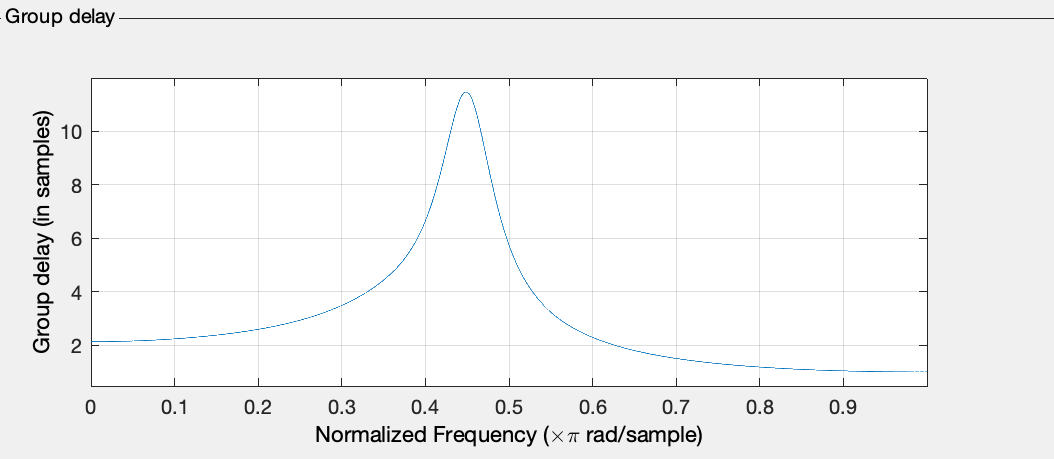

There are other filter design methods as well, as you might have noted in the Filter Designer tool. However, we are not interested in them in this course. You now have sufficient knowledge on filter design and analysis. Hence, if required, you should be able to pick them up easily when required. 

### Thank you!